Initializing Variables

t = 0.001; %decrease time increments to increase accuracy

%coeffecient of restitution between cue ball and numbered balls
e_cn = 0.95;
%coeffecient of restitution between numbered balls
e_nn = 0.9;
%coeffecient of restitution between any ball and wall
e_bw = 0.7; 
%friction between any balls
f_bb = 0.05;
%friction between ball and wall
f_bw = 0.2;

% Initail co-ordinates of the balls (in inches)
b1 = [22.91, 28.45];
b2 = [31.02, 40.25];
b3 = [4.55, 37.32];
b4 = [18.88, 38.92];
b5 = [5.39, 30.40];
b6 = [22.53, 5.54];
b7 = [24.61, 12.30];
b8 = [13.85, 16.00];
b9 = [36.56, 37.66];
b10 = [31.33, 30.65];
b_c = [66.00, 22.00]; 

%Initial velocities of the numbered balls
v1 = [0; 0];
v2 = [0; 0];
v3 = [0; 0];
v4 = [0; 0];
v5 = [0; 0];
v6 = [0; 0];
v7 = [0; 0];
v8 = [0; 0];
v9 = [0; 0];
v10 = [0; 0];

%keyset are all the keys referencing the different balls, 11 being the cue
keySet = {1,2,3,4,5,6,7,8,9,10,11};
%valueset are all the coordinte vector values for all the balls stored in a
%container
valueSet1 = {b1, b2, b3, b4, b5, b6, b7, b8, b9, b10, b_c};
%mapping the keys in the keyset to the values in the valueset, essentially
%creating a dictionary and making it easier to refer to a ball's position
P = containers.Map(keySet, valueSet1);


% For Question 2: Part 4: Finding the angle to the closest ball to cue ball

%Set a very large initial minimum length variable
min_lenght = 1e10;
%set the closest ball to be a arbitrary variable, 0
close_ball = 0;

%iterate through all the numbered balls
for h = 1:10
%   distance vector between the cue ball and the numbered ball currently
%   being iterated through
    diff = P(h)-b_c;

%   if the norm of the vector is less than the min length, then set the min
%   length to that norm and set the closeset ball to be the ball referred
%   in the current iteration

    if (norm(diff) < min_lenght)
        min_lenght = norm(diff);
        close_ball = h;
    end
end

% distance vector between the cue ball and the closest numbered ball
close_vector = P(close_ball)-b_c;

% angle between the above distance vector and the x-axis
theta = atan(abs(close_vector(2)/close_vector(1)));

% add an angle here to for Question 2, case 1,2,3
% This angle will overide the prevously found angle
% Prevoius "theta" is for head on collsion with closest ball
% Here theat set to 15 degrees for case 2
theta = deg2rad(0);



% setting the velocity of the cue ball (this is for case 2, for other cases
% set the velocity to the one specified in the quesition)
v_imp = convert_vel(4); %convert the vel input(in m/s) to inch/sec
v_x_deg = -1*v_imp*cos(theta); % x_component of the velocity
v_y_deg = v_imp*sin(theta); % y_component of the velocity
v_c = [v_x_deg; v_y_deg]; % velocity vector of the cue ball


%set up value sets for all the balls velocities and masses and map them to
%the keyset
valueSet2 = {v1, v2, v3, v4, v5, v6, v7, v8, v9, v10, v_c};
valueSet3 = {160, 160, 160, 160, 160, 160, 160, 160, 160, 160, 200}; %units do not matter
V = containers.Map(keySet, valueSet2);
M = containers.Map(keySet, valueSet3);


%initializing animation related variables an empty postition matrix
dInput = zeros(11, 2);
%an empty velocity matrix later used for checking when to end the
%animation/main loop
v_mat = zeros(11,2);

%an empty cell, later filled with positions of the balls at each frame/time
%increment
Bp_final = cell(10000, 1);

exit = true;

% count 3 represents the number of frames/time increments
count3 = 1;

Frame Loop

%loop increments by time 't'
while(exit)
% crash tracker to track which balls have been in a collison, 1 means the
% ball has collided
crash_tracker = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]; 
% Iterate through the balls
    for count = 1:11
        % set the velocity and position of the current ball 'A' in the
        % iteration
        p_a = P(count);
        v_a = V(count);
        
        
        % if the magnitude of velocity is not zero
        if (norm(v_a) ~= 0)
            %if the ball is in contact with the left wall
            if (p_a(1) <= 2.25)
                overlap = abs(2.25 - p_a(1)); %correct for overlap of ball and wall
                correct_a = p_a + [overlap, 0]; %correct for overlap of ball and wall
                P(count) = correct_a; %correct for overlap of ball and wall
                V(count) = wall_crash(v_a, e_bw, f_bw, "L"); % find the velocity of the ball after collision with the wall
                
            %else if the ball is in contact with the right wall
            elseif (p_a(1) >= (88-2.25))
                overlap = abs((88-2.25) - p_a(1)); %correct for overlap of ball and wall
                correct_a = p_a - [overlap, 0]; %correct for overlap of ball and wall
                P(count) = correct_a;  %correct for overlap of ball and wall
                V(count) = wall_crash(v_a, e_bw, f_bw, "R");% find the velocity of the ball after collision with the wall
                
            % else if the ball is in contact with the bottom wall
            elseif (p_a(2) <= 2.25)
                overlap = abs(2.25 - p_a(2)); %correct for overlap of ball and wall
                correct_a = p_a + [0, overlap]; %correct for overlap of ball and wall
                P(count) = correct_a; %correct for overlap of ball and wall
                V(count) = wall_crash(v_a, e_bw, f_bw, "B"); % find the velocity of the ball after collision with the wall
              
            %else if the ball is in contact with the top wall
            elseif (p_a(2) >= (44-2.25))
                overlap = abs((44-2.25) - p_a(2)); %correct for overlap of ball and wall
                correct_a = p_a - [0, overlap]; %correct for overlap of ball and wall
                P(count) = correct_a; %correct for overlap of ball and wall
                V(count) = wall_crash(v_a, e_bw, f_bw, "T"); % find the velocity of the ball after collision with the wall
                
            end
            
            
            %iterate through the balls
            for count1 = 1:11
                %set the velocity and position of the ball 'B' in the
                %current iteration as a seperate variable
                p_b = P(count1);
                v_b = V(count1);
                
                %find the distance between the center of the ball in the
                %parent iteration ('A') and this iteration ('B')
                d = norm(p_a - p_b); %radius is 2.25" everywhere
                
                % if the balls are colliding and the balls 'A' and 'B' are
                % not the same and they have not already collided
                if ((abs(d) < 2.25*2) && (count ~= count1) && (crash_tracker(count) == 0 || crash_tracker(count1) == 0))
                    
                    % this chunck of code is to correct any overlapping
                    unit_vect = (p_b - p_a)/norm(p_b - p_a); % going from a to b
                    vel_ratio = norm(v_a)/(norm(v_a) + norm(v_b)); %instead of just dividing 50/50 want ratio of velocties
                    overlap = 2.25*2 - norm(p_b - p_a);
                    correct_a = p_a - unit_vect*overlap*vel_ratio; % new pos to correct overlap of the ball a
                    correct_b = p_b + unit_vect*overlap*(1-vel_ratio); % new correct overlap of the ball b
                    P(count) = correct_a; %update main containers with corrected value
                    P(count1) = correct_b;
                    
                    % if either of ball 'A' or ball 'B' is a cue ball
                    if count == 11 || count1 == 11
                        % find the final velocities of the ball after
                        % collison and store them in temp variables
                        [tempA, tempB] = ball_crash(v_a, v_b, correct_a, correct_b, M(count), M(count1), e_cn, f_bb);    
                    %else the collison is between numbered balls
                    else
                        % find the final velocities of the ball after
                        % collison and store them in temp variables
                        [tempA, tempB] = ball_crash(v_a, v_b, correct_a, correct_b, M(count), M(count1), e_nn, f_bb);
                    end
                    
                    
                    %update the velocity container with the new velocity of
                    %the two balls after collison
                    V(count) = tempA;
                    V(count1) = tempB;
                    
                    % show the collison took place for these two balls by
                    % updating the crash tracker
                    crash_tracker(count) = 1;
                    crash_tracker(count1) = 1;
                end
            end
        end
    end
    
    %increment all moving balls and account for friction of the surface
    
    %iterate through all the balls
    for count2 = 1:11
        %for ball 'i' in the current iteration, set its velocity and
        %position as seperate variables
        v_i = V(count2);
        p_i = P(count2);
        
        %if the velocity of ball 'i' is not zero
        if (norm(v_i) ~= 0)
            %find the new velocity and position of ball 'i' after time
            %increment t
            [tempV, tempP] = increment(v_i, p_i, t);
            %update the containers for ball 'i'
            V(count2) = tempV;
            P(count2) = tempP;
        end
    end
    
    
    
    %following block code is to check whether all the balls have stopped
    %moving their velocities are all zero
    
    %iterate through the balls
    for x = 1:11
        %for each ball 'x' store its position and velocities in its
        %corresponding matrix spot
        dInput(x,:) = P(x);
        v_mat(x,:) = V(x);
    end
    
    %if all the velocities in the matrix is zero (its norm is zero)
    if (norm(v_mat) == 0)
        % make exit false, meaning stop the frame loop/animation
        exit = false;
    end
    
    %for each frame/time increment save the positions of the ball
    
    %each frame will have its corresponding set of positions for the balls
    Bp_final{count3} = dInput; 
    %increment count3 by 1
    count3 = count3 + 1;
end


Animation

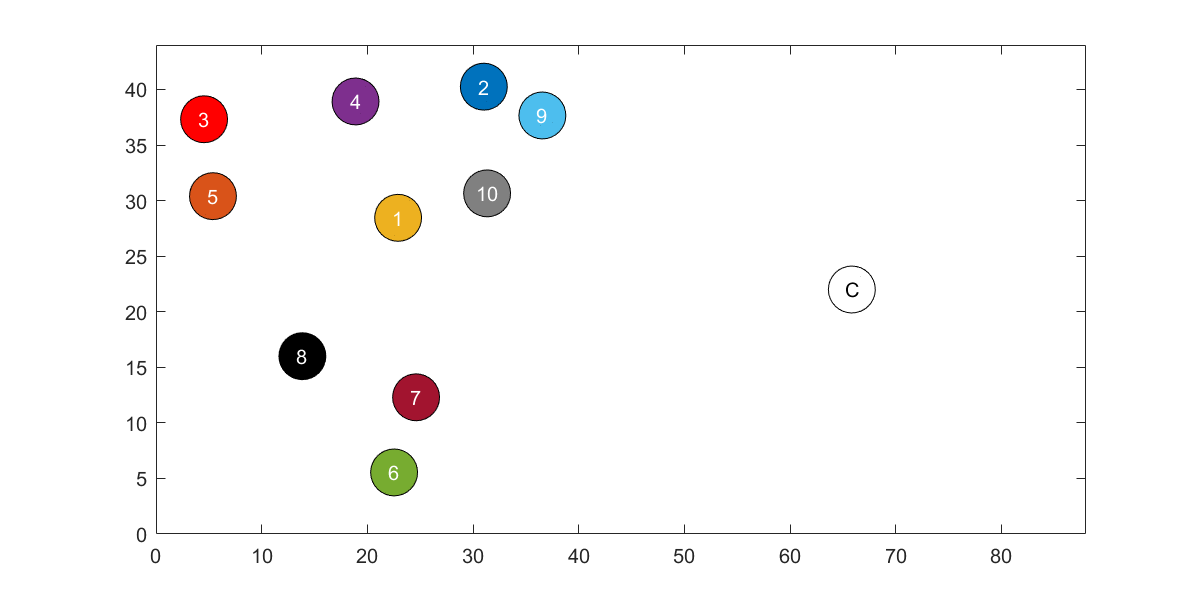

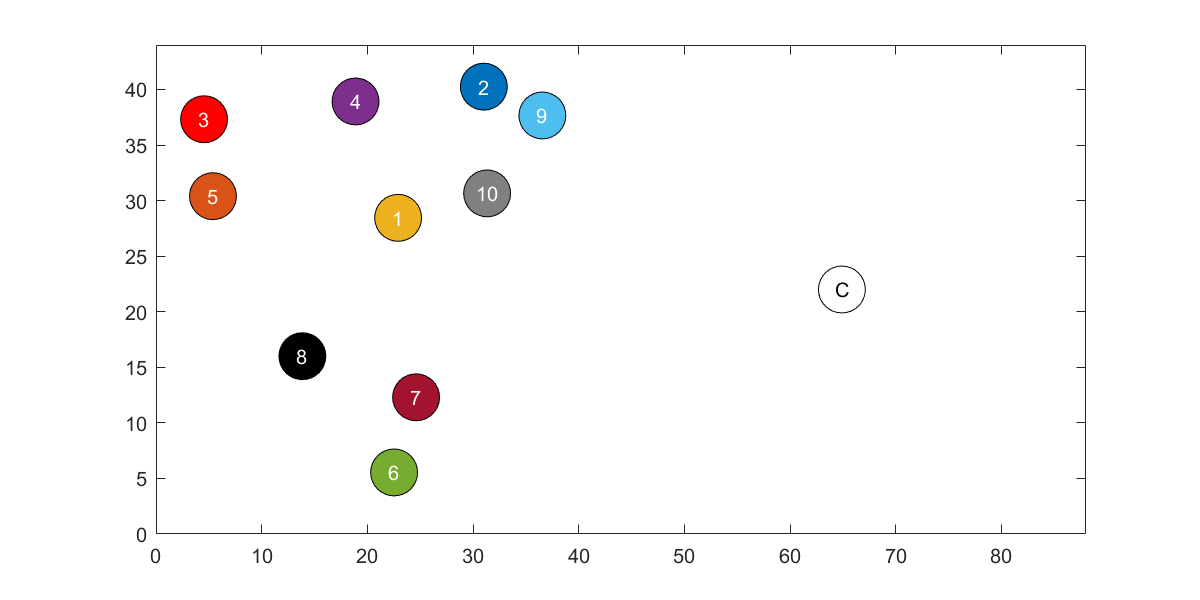

%block of code to find how many frame/time increments are stored in the
%Bp_final cell array (how many cells are populated)

w = true;
%index to iterate through Bp_final cell array
count4 = 1;
Bp_size = 0; %number of populated cells (time increments/frames present)
while(w)
    if norm(Bp_final{count4}) ~= 0
        Bp_size = Bp_size + 1;
    else
        w = false;
    end
    count4 = count4 + 1;
end
disp(Bp_final{Bp_size});



%block of code to animate the frames present in the frame cell
pause on
figure
box on
% set the pool table board
set(gcf, 'Position',  [100, 100, 800, 400])
xlim([0 88])
ylim([0 44])
%iterate through each frame
for j = 1:Bp_size
    clf % Clears the previous contents of the figure. 
    %iterate through each ball
    for i = 1:11
        hold on
        %set the ball in its corresponding position in the frame on the
        %table
        scatter(Bp_final{j}(i,1),Bp_final{j}(i,2),550,'filled','MarkerEdgeColor','k','LineWidth',0.5);
        if i == 8
            % setting the number on the 8 ball
            text(Bp_final{j}(i,1),Bp_final{j}(i,2),num2str(i),'HorizontalAlignment','center','Color',[1 1 1]);
        elseif i == 11
            % setting the tect on the cue ball
            text(Bp_final{j}(i,1),Bp_final{j}(i,2),'C','HorizontalAlignment','center');
        else
            %setting the number and color on any numbered balls (except 8)
            text(Bp_final{j}(i,1),Bp_final{j}(i,2),num2str(i),'HorizontalAlignment','center','Color',[1 1 1]);
        end
    end
    % setting the color for all the balls
    colororder([0.9290 0.6940 0.1250; 0 0.4470 0.7410;1 0 0;0.4940 0.1840 0.5560;0.8500 0.3250 0.0980; ...
        0.4660 0.6740 0.1880;0.6350 0.0780 0.1840;0 0 0;0.3010 0.7450 0.9330;0.5 0.5 0.5;1 1 1])
    xlim([0 88])
    ylim([0 44])
    box on
    pause(0.01) % Pause for 0.01 s before updating the figure.
end 


disp("DONE");

DONE


Collison and Increment Functions

function [va2, vb2] = ball_crash(va1, vb1, a_pos, b_pos, ma, mb, e, f) 
% function to deal with the ball to ball collisons takes in initial
% velocities, positions, masses of the two colliding ball, coeffecient of
% restitution  b/w them and the friction b/w them returns the final
% velocities of the two balls (in x-y system) after collisons



% relative position of ball 'b' with respect to ball 'a'
relative_pos = b_pos - a_pos; 
% angle of the relative position vector with the x-axis
angle = atan2(relative_pos(2), relative_pos(1));

% rotation matrix to go from x-y to n-t system
rotate = [cos(angle), sin(angle); -sin(angle), cos(angle)];
% rotation matrix to go from n-t to x-t system
rotate_back = [cos(angle), -sin(angle); sin(angle), cos(angle)];

% initial velocities of the ball in n-t coordinate system
va_rotate = rotate*va1;
vb_rotate = rotate*vb1;

% assigning n-t components of the velocities as seperate variables
va1_n = va_rotate(1);
va1_t = va_rotate(2);
vb1_n = vb_rotate(1);
vb1_t = vb_rotate(2);

% relative tangential vel vector of 'b' with respect to 'a'
relative_vt = vb1_t - va1_t;
sign = relative_vt/abs(relative_vt); % determines sign (direction) of tangential vel ball B relative to A

%find the normal velocities of two balls after collison using the equations
%documented in the report
vb2_n = (ma*va1_n*(1+e) + vb1_n*(mb-ma*e))/(ma+mb);
va2_n = e*(vb1_n-va1_n) + vb2_n;

if abs(relative_vt) > 1e-10 % if there exists significant relative tangential motion
    %find the tangential velocities of two balls after collison using
    %impulse momentum theorem
    va2_t = va1_t + sign*f*abs(va2_n-va1_n); % here "sign" is used to detemine direction of fricton
    vb2_t = vb1_t - sign*f*abs(vb2_n-vb1_n);
else 
    % if very small relative tangential motion, friction is ignored and the final tangential velocities remain the same
    va2_t = va1_t;
    vb2_t = vb1_t;
end

% Rotate back to x-y system, and return the final velocities (in x-y) of
% balls after collison
va2 = rotate_back*[va2_n; va2_t];
vb2 = rotate_back*[vb2_n; vb2_t];
end




function [va2] = wall_crash(va1, e, f, wall) 
% function for dealing with ball-wall collisons and returns final velocity
% of the ball after the collison takes vel of the ball, coeff. of
% restitution, friction, and wall as input parameters


    %check which wall did the ball hit, and accordingly set the angle
    %between them
    if (wall == "L")
        angle = pi;
    elseif (wall == "T")
        angle = pi/2;
    elseif (wall == "R")
        angle = 0;
    elseif (wall == "B")
        angle = -pi/2;
    end

    % Rotation Matrix to map from x-y to n-t system
    rotate = [cos(angle), sin(angle); -sin(angle), cos(angle)];
    % Matrix to map from n-t system back to x-y
    rotate_back = [cos(angle), -sin(angle); sin(angle), cos(angle)];
    
    % convert initial velocity of ball from x-y to n-t
    vc_rotate = rotate*va1;
    
    % Get initial velocity in n-t direction components
    va1_n = vc_rotate(1);
    va1_t = vc_rotate(2);
    
    % get the unit vector in the tangent direction for calculation of final
    % velocity component in t-direction
    sign = va1_t/abs(va1_t);
    
    % Calculate final velocity of the ball in n-t direction
    va2_n = va1_n*(0 - e);
    va2_t = va1_t - sign*f*abs(va2_n-va1_n);
    
    % Convert the final velocity from n-t back to x-y system If no
    % tangential velocities, if statments will ignore friction
    if (abs(va1_t) < 1e-10)
        va2 = rotate_back*[va2_n; 0];
    else
        va2 = rotate_back*[va2_n; va2_t];
    end
end



function [output_v, output_p] = increment(v, p, t) 
% updating balls position and velocity after time increment t (accounting
% for surface friction) takes in initial velocity and position of the ball
% and time increment t returns final velocity and position coordinates of
% the ball after a time increment t


% friction between any ball and the cushion surface
f_bs = 0.1;
% acceleration due to gravity in inch/s^2
g = 32.174*12; 
% angle of the initial velocity of the ball relative to the x-axis
phi = atan2 (v(2), v(1));
% calculate the deceleration due to friction in x and y direction
ax = -1*f_bs*g*cos(phi); %inch/s^2
ay = -1*f_bs*g*sin(phi); %inch/s^2
a = [ax; ay];
% find final velocity vector after the time increment
output_v = v + a*t; %time must be in seconds
% find the new position of the ball after the time increment
output_p = transpose(transpose(p) + v*t + 0.5*a*(t^2)); %time must be in seconds

% if the magnitude of the output velocity is bigger than the initial
% velocity, it means friction is accelerating the ball which is not
% possible, so set the final velocity to 0 for this case and the position
% remains the same.
if (norm(output_v) > norm(v))
    output_v = [0;0];
    output_p = p;
end
end



%this function converts the velocity input (in m/s) to (inch/s)
function inchs = convert_vel(ms)
inchs = ms*39.37;
end